# Solution of systems of nonlinear equations

Let $f\left(x\right)$ be a vector function $R^n \longrightarrow R^n$  

The Jacobian of $f\left(x\right)$ is the $n\times n$ matrix of first partial derivatives

Both the gradient and Jacobian are "first derivatives"

- gradient: first derivative of a scalar function of several variables 

- Jacobian: first derivative of a vector function of several variables

If $f\left(x\right)$ is a scalar function $R^n \longrightarrow R$, the Jacobian is reduced to a row vector of partial derivatives of $f\left(x\right)$, i.e. the transpose of its gradient.

The Jacobian of the gradient of a scalar function of several variables is the Hessian matrix: "second derivative" of the function in question.

## Primer sistema de ecuaciones


$$x_1^2 +x_1 x_2 =10$$



$$x_2 +3x_1 x_2^2 =57$$


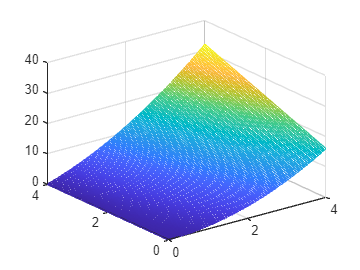

x1= linspace(0,4);
x2 = linspace(0,4);
[X1,X2] = meshgrid(x1,x2);
f1 = X1.^2 + X1.*X2;
mesh(X1,X2,f1);

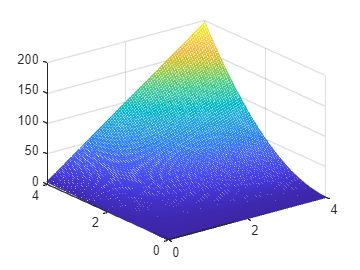

f2 = X2 + 3*X1.*X2.^2;
mesh(X1,X2,f2);

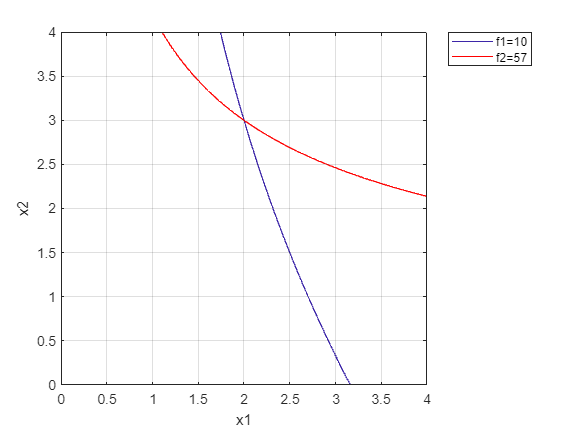

contour(X1, X2, f1,[10 10])
hold on;
contour(X1, X2, f2,[57 57],'r');
grid on;
hold off;
xlabel('x1');
ylabel('x2');
legend('f1=10','f2=57');

f = @(x) [ x(1)^2 + x(1)*x(2) - 10; 
           x(2)+ 3*x(1)*x(2)^2 - 57 ];
J = @(x) [ 2*x(1) + x(2), x(1);
           3*x(2)^2, 1 + 6*x(1)*x(2)];

x0 = [1; 1];
f(x0)

ans =     -8
   -53


[x,iter] = Par2_newtonRaphsonVV(f,J,x0)

x =     2.0000
    3.0000


iter = 8

f(x)

ans = 1.0e-14 *

   -0.1776
   -0.7105


## Segundo sistema de ecuaciones


$$3x_1 -\cos \left(x_2 x_3 \right)=\frac{3}{2}$$



$$4x_1^2 -625x_2^2 +2x_2 =1$$



$$e^{-x_1 x_2 } +20x_3 =-\frac{10\pi -3}{3}$$


syms x1 x2 x3
xs = [x1;x2;x3];
f1 = 3*xs(1)-cos(xs(3)*xs(2))-3/2;
f2 = 4*xs(1)^2-625*xs(2)^2+2*xs(2)-1;
f3 = exp(-xs(1)*xs(2))+20*xs(3)+(10*pi-3)/3;
fs = [f1; f2; f3]

$$fs = \left(\begin{array}{c} 3\,x_{1}-\cos\left(x_{2}\,x_{3}\right)-\frac{3}{2}\\ 4\,{x_{1}}^{2}-625\,{x_{2}}^{2}+2\,x_{2}-1\\ 20\,x_{3}+{\mathrm{e}}^{-x_{1}\,x_{2}}+\frac{5332248173269055}{562949953421312} \end{array}\right)$$

Js = jacobian(fs,xs)

$$Js = \left(\begin{array}{ccc} 3 & x_{3}\,\sin\left(x_{2}\,x_{3}\right) & x_{2}\,\sin\left(x_{2}\,x_{3}\right)\\ 8\,x_{1} & 2-1250\,x_{2} & 0\\ -x_{2}\,{\mathrm{e}}^{-x_{1}\,x_{2}} & -x_{1}\,{\mathrm{e}}^{-x_{1}\,x_{2}} & 20 \end{array}\right)$$

f = @(xs) [3*xs(1)-cos(xs(3)*xs(2))-3/2; 
           4*xs(1)^2-625*xs(2)^2+2*xs(2)-1;
           exp(-xs(1)*xs(2))+20*xs(3)+(10*pi-3)/3];
J = @(xs) [ 3, xs(3)*sin(xs(2)*xs(3)), xs(2)*sin(xs(2)*xs(3));
            8*xs(1), 2-1250*xs(2), 0;
            -xs(2)*exp(-xs(1)*xs(2)), -xs(1)*exp(-xs(1)*xs(2)), 20];

x0 = [1; 1; 1];
[x,iter] = Par2_newtonRaphsonVV(f,J,x0)

x =     0.8332
    0.0549
   -0.5214


iter = 10

## Tercer sistema de ecuaciones


$$2x_1 +x_2 +2x_3^2 \;=\;5$$



$$x_2^3 +4x_3 =4$$



$$x_1 x_2 +x_3 -e^{x_3 } =0$$


syms x1 x2 x3
xs = [x1;x2;x3];
f1 = 2*xs(1) + xs(2)+2*xs(3)^2 - 5;
f2 = xs(2)^3+4*xs(3)-4;
f3 = xs(1)*xs(2)+xs(3)-exp(xs(3));
fs = [f1; f2; f3]

$$fs = \left(\begin{array}{c} 2\,{x_{3}}^{2}+2\,x_{1}+x_{2}-5\\ {x_{2}}^{3}+4\,x_{3}-4\\ x_{3}-{\mathrm{e}}^{x_{3}}+x_{1}\,x_{2} \end{array}\right)$$

Js = jacobian(fs,xs)

$$Js = \left(\begin{array}{ccc} 2 & 1 & 4\,x_{3}\\ 0 & 3\,{x_{2}}^{2} & 4\\ x_{2} & x_{1} & 1-{\mathrm{e}}^{x_{3}} \end{array}\right)$$


f = @(xs) [ 2*xs(1) + xs(2)+2*xs(3)^2 - 5; 
           xs(2)^3+4*xs(3)-4;
           xs(1)*xs(2)+xs(3)-exp(xs(3))];
J = @(xs) [ 2, 1, 4*xs(3);
            0, 3*xs(2)^2, 4;
            xs(2), xs(1), 1-exp(xs(3))];

x0 = [1; 1; 1];
[x,iter] = Par2_newtonRaphsonVV(f,J,x0)

x =     1.4225
    0.9754
    0.7680


iter = 6

f(x)

ans = 1.0e-15 *

         0
         0
    0.4441


## Cuarto sistema de ecuaciones

Determine the points of intersection between the circle $x^2 +y^2 =3$ and the hyperbola $\textrm{xy}=1$.

f = @(x) [ x(1)^2+x(2)^2-3;
            x(1)*x(2)-1];
J = @(x) [ 2*x(1), 2*x(2);
            x(2), x(1)];

fprintf('Hay cuatro pares de soluciones:')

Hay cuatro pares de soluciones:

x0 = [1;2];
[x0,~] = Par2_newtonRaphsonVV(f,J,x0)

x0 =     0.6180
    1.6180


x1 = [2;1];
[x1,~] = Par2_newtonRaphsonVV(f,J,x1)

x1 =     1.6180
    0.6180


x2 = [-1;-2];
[x2,~] = Par2_newtonRaphsonVV(f,J,x2)

x2 =    -0.6180
   -1.6180


x3 = [-2;-1];
[x3,~] = Par2_newtonRaphsonVV(f,J,x3)

x3 =    -1.6180
   -0.6180


f(x0)

ans = 1.0e-15 *

         0
    0.2220


## Problema 12.8 Chapra 4ed

% f = [f1(x,y); f2(x,y)]
% y = -x^2 + x + 0.75
% y + 5*x*y = x^2
% initial guess x=y=1.2
% Sea v=[x;y]   x=v(1), y=v(2)
f = @(v) [v(2)+v(1)^2-v(1)-0.75;
          v(2) + 5*v(1)*v(2) - v(1)^2];
J = @(v) [2*v(1)-1, 1;
          5*v(2)-2*v(1), 1+5*v(1)];
v0=[1.2;1.2];
[v,iter] = Par2_newtonRaphsonVV(f,J,v0)

v =     1.3721
    0.2395


iter = 7

f(v)

ans =      0
     0


## Problema 12.17 Chapra 4ed

Determine the positive root of

y = x^2 + 1 

y = 2*cos x

Use a graphical approach to obtain your initial guesses

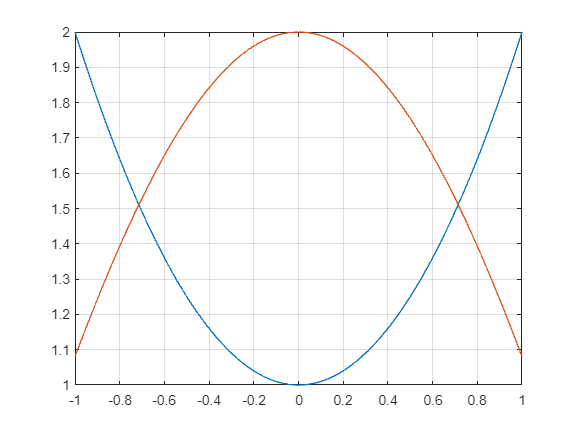

f1 = @(x) x.^2+1;
f2 = @(x) 2*cos(x);

fplot(f1, [-1 1])
hold on
fplot(f2, [-1 1])
grid on
hold off


f = @(v) [v(1)^2+1-v(2);
          2*cos(v(1))-v(2)];
J = @(v) [2*v(1), -1;
          -2*sin(v(1)), -1];

v0=[.75;1.5];
[v,iter] = Par2_newtonRaphsonVV(f,J,v0)

v =     0.7146
    1.5107


iter = 5

v0=[-.75;1.5];
[v,iter] = Par2_newtonRaphsonVV(f,J,v0)

v =    -0.7146
    1.5107


iter = 5

f(v)

ans = 1.0e-15 *

    0.2220
   -0.2220


## Jacobiano simbólico

% jacobian(f,v) computes the Jacobian matrix of f with respect to v. 
% The (i,j) element of the result is df(i)/dv(j) (partial derivatives)
syms x1 x2
xs = [x1;x2];
f1 = xs(1)^2 + xs(1)*xs(2) - 10;
f2 = xs(2) + 3*xs(1)*xs(2)^2 - 57;
fs = [f1; f2]

$$fs = \left(\begin{array}{c} {x_{1}}^{2}+x_{2}\,x_{1}-10\\ 3\,x_{1}\,{x_{2}}^{2}+x_{2}-57 \end{array}\right)$$

Js = jacobian(fs,xs)

$$Js = \left(\begin{array}{cc} 2\,x_{1}+x_{2} & x_{1}\\ 3\,{x_{2}}^{2} & 6\,x_{1}\,x_{2}+1 \end{array}\right)$$

f = matlabFunction(fs)      % @(xs1,xs2)

f = function_handle with value:
    @(x1,x2)[x1.*x2+x1.^2-1.0e+1;x2+x1.*x2.^2.*3.0-5.7e+1]


f(1,2)

ans =     -7
   -43


J = matlabFunction(Js)      % @(xs1,xs2) reshapes into a 2x2 matrix

J = function_handle with value:
    @(x1,x2)reshape([x1.*2.0+x2,x2.^2.*3.0,x1,x1.*x2.*6.0+1.0],[2,2])


J(1,2)

ans =      4     1
    12    13


Función Newton-Raphson

% function [x,i] = newtonRaphsonVV(f,J,x)
%     %Parámetros iniciales
%     max = 52;
%     tol = eps;
%     cond =  true;
%     i=0;
% 
%     while cond
%         xp = x;
%         x = xp-J(xp)\f(xp);    
%         i = i+1;
%         cond = norm((x-xp)./x, "Inf") > tol && i < max;
%     end
% end